clear; close all;

Kff = 2×2 cell array
    {[    3.5759e-006 5.7183e-003 59.5873e-003 50.0366e-018]}    {[-1.7165e-006 -2.7391e-003 -54.1831e-018 0.0000e+000]}
    {[-1.7165e-006 -2.7391e-003 -44.2171e-018 -69.9022e-033]}    {[   3.5759e-006 5.7102e-003 46.6958e-003 0.0000e+000]}


str11 = '3.575853e-06,5.718267e-03,5.958733e-02,5.003664e-17,'

str12 = '-1.716522e-06,-2.739130e-03,-5.418308e-17,            0,'

str21 = '-1.716522e-06,-2.739130e-03,-4.421709e-17,-6.990216e-32,'

str22 = '3.575853e-06,5.710188e-03,4.669578e-02,           0,'

{ { {3.575853e-06,5.718267e-03,5.958733e-02,5.003664e-17,},{-1.716522e-06,-2.739130e-03,-5.418308e-17,            0,} }, { {-1.716522e-06,-2.739130e-03,-4.421709e-17,-6.990216e-32,},{3.575853e-06,5.710188e-03,4.669578e-02,           0,} } }


most_recent_file = '20230326_time2246.csv'

## Compute Bezier curves

q0 = [0;0];
v0 = [0;0];

P0 = [0;0];
P1 = [0.1;1];
P2 = [0.2;0.5];
P3 = [1;1];

B = @(u) (1-u).^3.*P0 + 3*(1-u).^2.*u.*P1 + 3*(1-u).*u.^2.*P2 + u.^3.*P3;
xy1 = B(0:0.01:1);

dP = P2 - P3;
m = dP(2)/dP(1)


m =    625.0000e-003


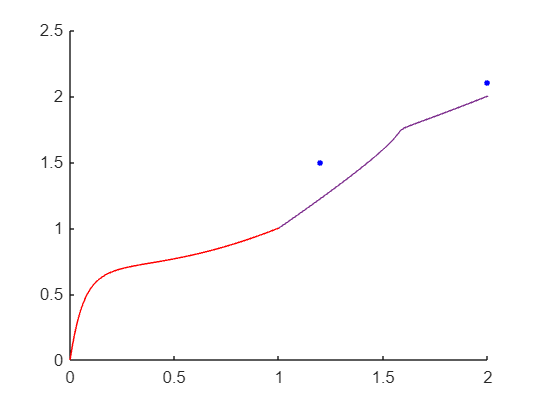


P0 = P3;
P1 = [2;2.1];
P2 = [1.2;1.5];
P3 = [2;2];

B = @(u) (1-u).^3.*P0 + 3*(1-u).^2.*u.*P1 + 3*(1-u).*u.^2.*P2 + u.^3.*P3;
xy2 = B(0:0.01:1);

% line1 = [];
% line2 = [];
% 
% for u = 0:0.01:1
%     line1(end+1,:) = [(1-u).*P0(1)+u.*P1(1), (1-u).*P0(2)+ u.*P1(2)];
%     line2(end+1,:) = [(1-u).*P2(1)+u.*P3(1), (1-u).*P2(2)+ u.*P3(2)];
% end

% figure;
% plot(0:0.01:1, xy(1,:))
figure;
hold on
plot(P1(1), P1(2), 'b.', 'markersize', 10);
plot(P2(1), P2(2), 'b.', 'markersize', 10);
% plot(line1(:,1), line1(:,2))
% plot(line2(:,1), line2(:,2))
% point(P2);
plot(xy1(1,:), xy1(2,:), '-r')
plot(xy2(1,:),xy2(2,:))